# Dimension generator for patch antenna

## Antenna properties

%% Adjust the required frequency and dielectric constant
fv = 6.2e9; % in GHz
er = 2.55;

## Set the bounds for the antenna

% Length (in mm)
lmin = 10;
lmax = 25;

% Height (in mm)
hmin = 0.01;
hmax = 1;

% Width (in mm)
wmin = 1;
wmax = 25;

% Total points to run the algorithm
RefPoints = 100;

## Generator

% Bounds (L, W, H)
L =  [lmin wmin hmin 0];
U =  [lmax wmax hmax 0.9999];

N = 3;
Functions = {@(x)f1(x, fv, er), @f2};
M = length(Functions);

f1_vals = zeros(1, RefPoints);
f2_vals = zeros(1, RefPoints);

rng(42);
X = {};

i = 1;
while i <= RefPoints
    z = [1e-8 0.01]; % Initial decision vector
    w = [0.5 0.5]; % adjust priority
    w = w / norm(w); % Normalize `w'
    
    assert (length(z) == M);
    assert (length(w) == M);
    
    % Non-Linear Conditions for ASF
    C1 = @(x) ASFCondition(x(1:N), Functions{1}, z(1), w(1));
    C2 = @(x) ASFCondition(x(1:N), Functions{2}, z(2), w(2));
    
    % Final Objective function
    Objective = @(x) ASF(x, Functions, M, z, w);
    
    % Make a proper guess which satisfies the constraints
    fprintf("[%2d] Getting feasible solution ...\n", i);
    x0 = rand(1, N+1) .* U;
    while C1(x0) > 0 || C2(x0) > 0
         x0 = rand(1, N+1) .* U;
    end
    
    fprintf("[%2d] Solving ...\n", i);
    options = optimoptions('fmincon', ...
        'Algorithm', 'sqp', ...
        'TolFun', 1e-9, ...
        'TolX', 1e-9, ...
        'MaxFunctionEvaluations', 1e5, ...
        'Display', 'none');
    [x, fval, exitflag, output] = fmincon(@(x)x(4), x0, [], [], [], [], ...
        L, U, ...
        @(x)Constraint(x, C1, C2), options);
    
    % Don't add the solution if it converges to an infeasible point
    if exitflag < 0
        continue;
    end
    
    X{i} = x;
    f1_vals(i) = Functions{1}(x);
    f2_vals(i) = Functions{2}(x);
    i = i+1;
end

[ 1] Getting feasible solution ...


[ 1] Solving ...


[ 2] Getting feasible solution ...


[ 2] Solving ...


[ 3] Getting feasible solution ...


[ 3] Solving ...


[ 4] Getting feasible solution ...


[ 4] Solving ...


[ 5] Getting feasible solution ...


[ 5] Solving ...


[ 6] Getting feasible solution ...


[ 6] Solving ...


[ 7] Getting feasible solution ...


## Results

fprintf("Optimal results:\n")

Optimal results:


[x, idx]= min(f1_vals);
fprintf("Dimensions:");

Dimensions:

disp(X{idx}(1:3));

   15.1577    9.3553    0.0100


fprintf("Error:");

Error:

disp(f1_vals(idx));

   9.0602e-06


## Plots

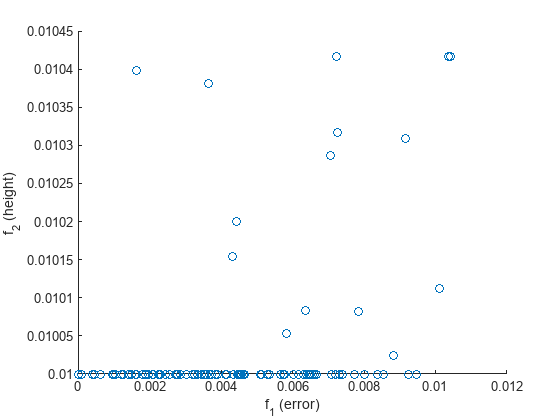

scatter(f1_vals, f2_vals);
xlabel("f_1 (error)");
ylabel("f_2 (height)");

## Functions

function ret = f1(x, fv, er)
    l = x(1) * 1e-3;
    W = x(2) * 1e-3;
    h = x(3) * 1e-3;
    
    ep_w = (er+1)/2 + (er-1)/(2 * sqrt(1 + 10*h/W));
    delta_w = 0.412 * h * ((ep_w+0.3)*(W/h+0.264))/((ep_w-0.258)*(W/h+0.813));
    fr = 3e8 ./ (2 * (l + delta_w) * sqrt(ep_w));
    ret = abs(fv-fr) * 1e-9;
end

function ret = f2(x)
    ret = x(3);
end
    
function ret = ASFCondition(x, Fn, z, w)
    ret = (Fn(x) - z) ./ w - x(end);
end

function [c, ceq] = Constraint(x, C1, C2)
    c = [C1(x); C2(x)];
    ceq = [];
end

function ret = ASF(x, Functions, M, z, w)
    C = zeros([1 M]);

    x = x(1:end-1);
    for i = 1:M
        C(i) = (Functions{i}(x) - z(i)) ./ w(i);
    end
    ret = max(C);
end
